% MATLAB Code - Complete Analysis
% Load the GSW dataset
gsw_data = readtable('GSW_YearlyHistory_nodata_60deltas.csv');

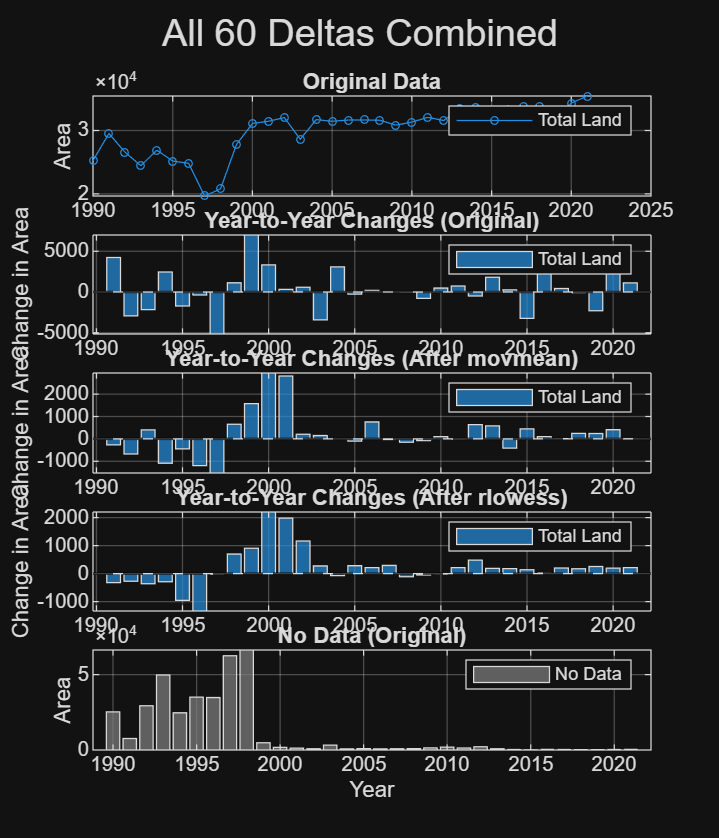


% Parse water data columns
years = 1984:2021;
n_years = length(years);
n_deltas = height(gsw_data);

% Initialize matrices for each water type
notwater_df = zeros(n_years, n_deltas);
seasonal_water_df = zeros(n_years, n_deltas);
water_df = zeros(n_years, n_deltas);
nodata_df = zeros(n_years, n_deltas);

% Parse string arrays to numeric matrices
% The CSV contains arrays like "[1.0, 2.0, 3.0, ...]"
for i = 1:n_deltas
    % Remove brackets and parse as numeric array
    notwater_str = gsw_data.notwater{i};
    notwater_str = strrep(notwater_str, '[', '');
    notwater_str = strrep(notwater_str, ']', '');
    notwater_df(:, i) = str2num(notwater_str)';
    
    seasonal_water_str = gsw_data.seasonal_water{i};
    seasonal_water_str = strrep(seasonal_water_str, '[', '');
    seasonal_water_str = strrep(seasonal_water_str, ']', '');
    seasonal_water_df(:, i) = str2num(seasonal_water_str)';
    
    water_str = gsw_data.water{i};
    water_str = strrep(water_str, '[', '');
    water_str = strrep(water_str, ']', '');
    water_df(:, i) = str2num(water_str)';
    
    nodata_str = gsw_data.nodata{i};
    nodata_str = strrep(nodata_str, '[', '');
    nodata_str = strrep(nodata_str, ']', '');
    nodata_df(:, i) = str2num(nodata_str)';
end

% Create total land dataframe
total_land_df = seasonal_water_df + notwater_df;

% Filter data from 1990 onwards
start_idx = find(years == 1990);
years_1990 = years(start_idx:end);
notwater_df_1990 = notwater_df(start_idx:end, :);
seasonal_water_df_1990 = seasonal_water_df(start_idx:end, :);
water_df_1990 = water_df(start_idx:end, :);
nodata_df_1990 = nodata_df(start_idx:end, :);
total_land_df_1990 = total_land_df(start_idx:end, :);

% Step 1: Apply movmean (moving average with window=5)
% dim=1 means operate along rows (for each delta column)
notwater_movmean = movmean(notwater_df_1990, 5, 1);
seasonal_water_movmean = movmean(seasonal_water_df_1990, 5, 1);
total_land_movmean = notwater_movmean + seasonal_water_movmean;
nodata_movmean = movmean(nodata_df_1990, 5, 1);

% Step 2: Apply rlowess smoothing (robust locally weighted scatterplot smoothing)
% dim=1 means operate along rows, window=5
notwater_smooth = smoothdata(notwater_movmean, 1, 'rlowess', 5);
seasonal_water_smooth = smoothdata(seasonal_water_movmean, 1, 'rlowess', 5);
total_land_smooth = notwater_smooth + seasonal_water_smooth;
nodata_smooth = smoothdata(nodata_movmean, 1, 'rlowess', 5);

% Sum across all deltas (sum along dimension 2 = columns)
total_land_all = sum(total_land_df_1990, 2);
total_land_movmean_all = sum(total_land_movmean, 2);
total_land_smooth_all = sum(total_land_smooth, 2);
nodata_all = sum(nodata_df_1990, 2);
nodata_movmean_all = sum(nodata_movmean, 2);
nodata_smooth_all = sum(nodata_smooth, 2);

% Calculate year-to-year differences
total_land_diff_all = diff(total_land_all);
total_land_diff_movmean_all = diff(total_land_movmean_all);
total_land_diff_smooth_all = diff(total_land_smooth_all);
nodata_diff_all = diff(nodata_all);
nodata_diff_smooth_all = diff(nodata_smooth_all);

% For plotting differences, use years_1990(2:end) since diff removes first element
years_diff = years_1990(2:end);

% Plot 1: All 60 Deltas Combined - Total Land
figure('Position', [100 100 1200 1400]);

subplot(5,1,1)
plot(years_1990, total_land_all, 'o-', 'MarkerSize', 3)
ylabel('Area')
title('Original Data')
legend('Total Land')
grid on

subplot(5,1,2)
bar(years_diff, total_land_diff_all, 'FaceAlpha', 0.7)
hold on
yline(0, 'k--', 'LineWidth', 1)
hold off
ylabel('Change in Area')
title('Year-to-Year Changes (Original)')
legend('Total Land')
grid on

subplot(5,1,3)
bar(years_diff, total_land_diff_movmean_all, 'FaceAlpha', 0.7)
hold on
yline(0, 'k--', 'LineWidth', 1)
hold off
ylabel('Change in Area')
title('Year-to-Year Changes (After movmean)')
legend('Total Land')
grid on

subplot(5,1,4)
bar(years_diff, total_land_diff_smooth_all, 'FaceAlpha', 0.7)
hold on
yline(0, 'k--', 'LineWidth', 1)
hold off
ylabel('Change in Area')
title('Year-to-Year Changes (After rlowess)')
legend('Total Land')
grid on

subplot(5,1,5)
bar(years_1990, nodata_all, 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.7)
xlabel('Year')
ylabel('Area')
title('No Data (Original)')
legend('No Data')
grid on

sgtitle('All 60 Deltas Combined')

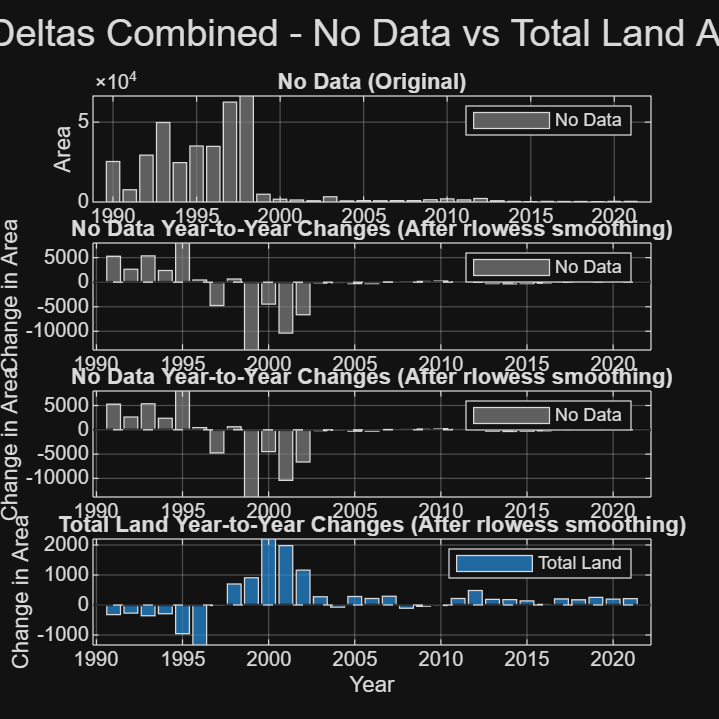


% Plot 2: No Data vs Total Land Analysis
figure('Position', [100 100 1200 1200]);

subplot(4,1,1)
bar(years_1990, nodata_all, 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.7)
ylabel('Area')
title('No Data (Original)')
legend('No Data')
grid on

subplot(4,1,2)
bar(years_diff, nodata_diff_smooth_all, 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.7)
hold on
yline(0, 'k--', 'LineWidth', 1)
hold off
ylabel('Change in Area')
title('No Data Year-to-Year Changes (After rlowess smoothing)')
legend('No Data')
grid on

subplot(4,1,3)
bar(years_diff, nodata_diff_smooth_all, 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.7)
hold on
yline(0, 'k--', 'LineWidth', 1)
hold off
ylabel('Change in Area')
title('No Data Year-to-Year Changes (After rlowess smoothing)')
legend('No Data')
grid on

subplot(4,1,4)
bar(years_diff, total_land_diff_smooth_all, 'FaceAlpha', 0.7)
hold on
yline(0, 'k--', 'LineWidth', 1)
hold off
xlabel('Year')
ylabel('Change in Area')
title('Total Land Year-to-Year Changes (After rlowess smoothing)')
legend('Total Land')
grid on

sgtitle('All 60 Deltas Combined - No Data vs Total Land Analysis')

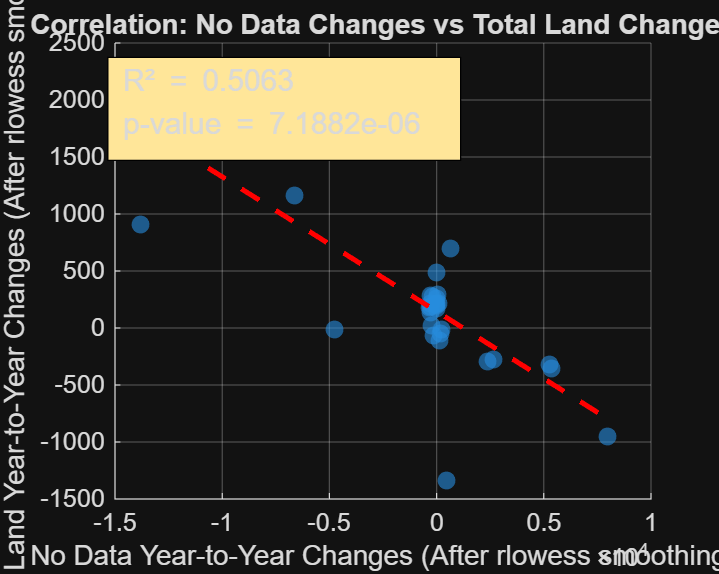


% Plot 3: Correlation Analysis
figure('Position', [100 100 1000 800]);

% Calculate correlation
[r_matrix, p_matrix] = corrcoef(nodata_diff_smooth_all, total_land_diff_smooth_all);
r_value = r_matrix(1,2);
r2 = r_value^2;
p_val = p_matrix(1,2);

% Create scatter plot
scatter(nodata_diff_smooth_all, total_land_diff_smooth_all, 50, 'filled', 'MarkerFaceAlpha', 0.6)
hold on

% Add trend line
coeffs = polyfit(nodata_diff_smooth_all, total_land_diff_smooth_all, 1);
x_fit = linspace(min(nodata_diff_smooth_all), max(nodata_diff_smooth_all), 100);
y_fit = polyval(coeffs, x_fit);
plot(x_fit, y_fit, 'r--', 'LineWidth', 2)

% Add R² text box
text_str = sprintf('R² = %.4f\\newlinep-value = %.4e', r2, p_val);
dim = [0.15 0.75 0.25 0.15];
annotation('textbox', dim, 'String', text_str, 'FitBoxToText', 'on', ...
     'FontSize', 12, 'BackgroundColor', [1 0.9 0.6], 'EdgeColor', 'k')

hold off
xlabel('No Data Year-to-Year Changes (After rlowess smoothing)')
ylabel('Total Land Year-to-Year Changes (After rlowess smoothing)')
title('Correlation: No Data Changes vs Total Land Changes')
grid on


% Save results to CSV files
writematrix([years', total_land_df], 'total_land_timeseries_matlab.csv')
writematrix([years', nodata_df], 'nodata_timeseries_matlab.csv')
writematrix([years_diff', total_land_diff_smooth_all], 'total_land_changes_smooth_matlab.csv')
writematrix([years_diff', nodata_diff_smooth_all], 'nodata_changes_smooth_matlab.csv')
